# ME 599 Thesis Analysis

By Connor Getz

Created: 12/1/2023                      Last Updated: 4/4/2024

clear
clc
close all

## Data Input and Organization

### Matrix Key:

#### Naming convension

T_0P -> Data for 0 grams of damping measured at the port

T _ [Damping material in grams] [P if port recording]

S1.000.W.01 -> Data set collected at the driver in first configuration with 0 grams of long fiber wool, data set one.

S [Port (P) or Driver ( )] [Configuration]. [Amount of Damping in Grams] . [Long Fiber Wool (W)] . [Data set number]

#### Matrix Locations

Columns 1-20 are the twenty sets of data taken

Column 21 is the simple mean of the twenty sets of data at each recorded frequency

### Importing Data Matrices:

% Corresponding Frequency
F_all = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Frequency');
% 0 grams of Damping
T_0 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.000.W.01');
T_0P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.000.W.01');
% 20 grams of Damping
T_20 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.020.W.01');
T_20P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.020.W.01');
% 30 grams of Damping
T_30 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.030.W.01');
T_30P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.030.W.01');
% 50 grams of Damping
T_50 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.050.W.01');
T_50P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.050.W.01');
% 70 grams of Damping
T_70 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.070.W.01');
T_70P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.070.W.01');
% 90 grams of Damping
T_90 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.090.W.01');
T_90P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.090.W.01');
% 110 grams of Damping
T_110 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.110.W.01');
T_110P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.110.W.01');
% 130 grams of Damping
T_130 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.130.W.01');
T_130P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.130.W.01');
% 150 grams of Damping
T_150 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.150.W.01');
T_150P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.150.W.01');
% 170 grams of Damping
T_170 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.170.W.01');
T_170P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.170.W.01');
% 190 grams of Damping
T_190 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.190.W.01');
T_190P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.190.W.01');
% 210 grams of Damping
T_210 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.210.W.01');
T_210P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.210.W.01');
% 230 grams of Damping
T_230 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.230.W.01');
T_230P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.230.W.01');
% 250 grams of Damping
T_250 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.250.W.01');
T_250P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.250.W.01');
% Data for Visuals
T_OB = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','DataforVisuals');
Scatter = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Scatter');
DfV = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','DataforVisuals');
Ar1 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area1');
Ar2 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area2');
Ar3 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area3');
Ar4 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area4');
Ar5 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area5');

## Visualizing the Data

Test_1 = T_0P(288,21)

Test_1 =   96.866649999999993


Test_2 = T_130P(288,21)

Test_2 =   86.303699999999992


Test_3 = T_250P(288,21)

Test_3 =   73.897199999999998


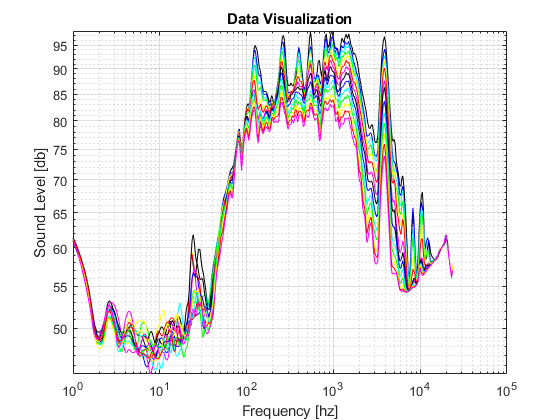



loglog(F_all, T_0P(:,21), 'k', F_all, T_20P(:,21), 'b', F_all, T_30P(:,21), 'c', F_all, T_50P(:,21), 'g', F_all, T_70P(:,21), 'y', F_all, T_90P(:,21), 'r', F_all, T_110P(:,21), 'm', F_all, T_130P(:,21), 'k', F_all, T_150P(:,21), 'b', F_all, T_170P(:,21), 'c', F_all, T_190P(:,21), 'g', F_all, T_210P(:,21), 'y', F_all, T_230P(:,21), 'r',F_all, T_250P(:,21), 'm')
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([-4 5]);
%xlim([3000 4000]);
title('Data Visualization');
ylabel('Sound Level [db]');
xlabel('Frequency [hz]');

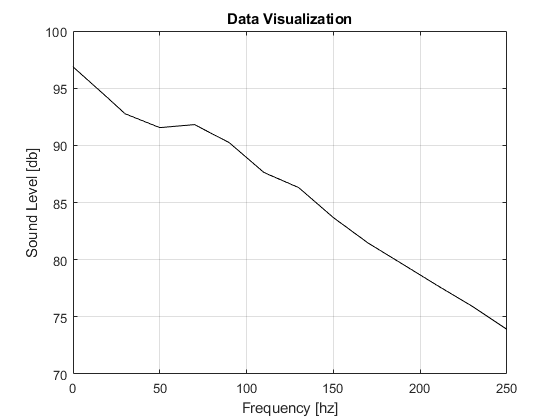

%legend('Mass Velocity','location','NE');

SPL_3870 = [T_0P(288,21); T_20P(288,21); T_30P(288,21); T_50P(288,21); T_70P(288,21); T_90P(288,21); T_110P(288,21); T_130P(288,21); T_150P(288,21); T_170P(288,21); T_190P(288,21); T_210P(288,21); T_230P(288,21); T_250P(288,21)];
Damping_Level = [0; 20; 30; 50; 70; 90; 110; 130; 150; 170; 190; 210; 230; 250];

plot(Damping_Level, SPL_3870, 'k')
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([-4 5]);
%xlim([3000 3900]);
title('Data Visualization');
ylabel('Sound Level [db]');
xlabel('Frequency [hz]');

%legend('Mass Velocity','location','NE');

## Model - Trial 1

### Enclosure Dimensions

Diameter = 0.1778;       % [m]
Length = 1.1303;         % [m]
a = Diameter/2;          % [m]
V = pi*Length*(a^2);     % [m^3]
c_0 = 343;               % [m/s]
S = pi*(a^2);            % [m^2]
L_a = Length + 0.85*a;   % [m]

### Enclosure Properties

m = 1.204 * V;           % Density from Engineering Toolbox at 20 degrees C
k = 1;                   % Spring Guess
c = 1;                   % Damping Guess

Figure 6

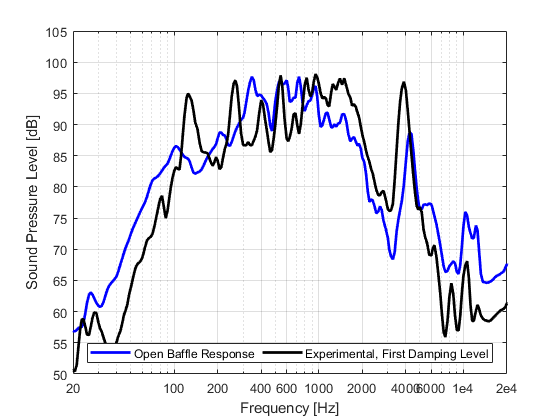

f6 = figure('Name','Figure 6: Open Baffle Response', ...
    'NumberTitle','off');
semilogx(F_all, T_OB(:,1),'b', 'LineWidth', 2);
hold on
semilogx(F_all, T_0P(:,21),'k', 'LineWidth', 2);
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([50 105]);
xlim([20 20000]);
%Adds title
xticks([20 100 200 400 600 1000 2000 4000 6000 10000 20000])
xticklabels({'20', '100', '200', '400', '600', '1000', '2000', '4000', '6000', '1e4', '2e4'})
%title('Total Frequency Response Graph');
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
lgd = legend('Open Baffle Response', 'Experimental, First Damping Level', 'location', 'S');
lgd.NumColumns = 2;

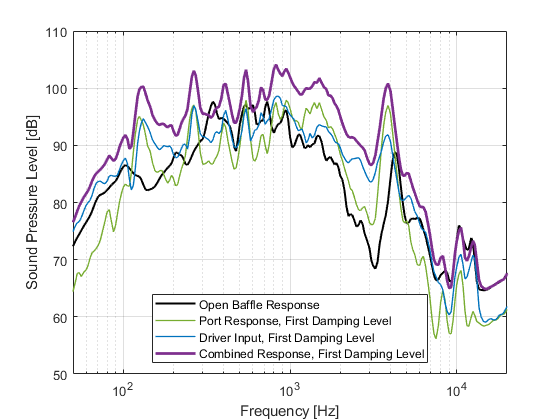

f7 = figure('Name','Figure 7: Effect on Stand on Frequency Response', ...
    'NumberTitle','off');
semilogx(F_all, T_OB(:,1),'k', 'LineWidth', 1.5);
hold on
semilogx(F_all, T_0P(:,1),'Color','#77AC30', 'LineWidth', 1);
semilogx(F_all, T_0(:,1),'Color','#0072BD', 'LineWidth', 1);
semilogx(F_all, T_0P(:,22),'Color','#7E2F8E', 'LineWidth', 2);
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([50 110]);
xlim([50 20000]);
%Adds title
%xticks([50 100 200 400 600 800 1000 1500 2000 3000])
%xticklabels({'50', '100', '200', '400', '600', '800', '1000', '1500', '2000', '3000'})
%title('Total Frequency Response Graph');
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
legend('Open Baffle Response', 'Port Response, First Damping Level', 'Driver Input, First Damping Level', 'Combined Response, First Damping Level', 'location', 'S')

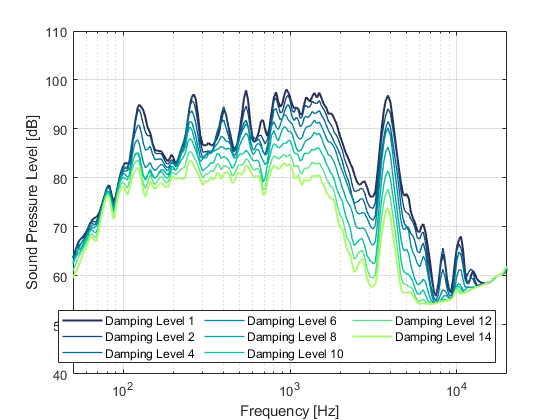

f8 = figure('Name','Figure 8: Experimental Response at Damping Levels', ...
    'NumberTitle','off');
semilogx(F_all, T_0P(:,21),'Color','#292f56', 'LineWidth', 1.5);
hold on
semilogx(F_all, T_20P(:,21),'Color','#154b7a', 'LineWidth', 1);
semilogx(F_all, T_50P(:,21),'Color','#006a94', 'LineWidth', 1);
semilogx(F_all, T_90P(:,21),'Color','#00889f', 'LineWidth', 1);
semilogx(F_all, T_130P(:,21),'Color','#00a6a4', 'LineWidth', 1);
semilogx(F_all, T_170P(:,21),'Color','#00c79c', 'LineWidth', 1);
semilogx(F_all, T_210P(:,21),'Color','#54e387', 'LineWidth', 1);
semilogx(F_all, T_250P(:,21),'Color','#acfa70', 'LineWidth', 1.5);
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([40 110]);
xlim([50 20000]);
%Adds title
%xticks([50 100 200 400 600 800 1000 1500 2000 3000])
%xticklabels({'50', '100', '200', '400', '600', '800', '1000', '1500', '2000', '3000'})
%title('Total Frequency Response Graph');
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
lgd = legend('Damping Level 1', 'Damping Level 2', 'Damping Level 4', 'Damping Level 6', 'Damping Level 8', 'Damping Level 10', 'Damping Level 12', 'Damping Level 14', 'location', 'S');
lgd.NumColumns = 3;

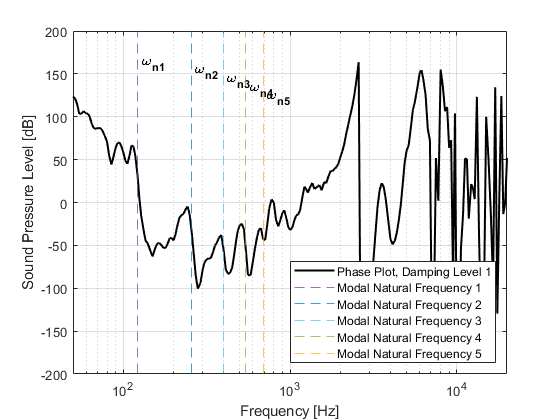

f9 = figure('Name','Figure 9: Phase Plot', ...
    'NumberTitle','off');
x = [122.5, 255.8, 397.3, 542.7, 690.1];
y = [150, 140, 130, 120, 110];
labels = {'\bf \omega_{n1}','\bf \omega_{n2}','\bf \omega_{n3}','\bf \omega_{n4}','\bf \omega_{n5}'};
semilogx(F_all, T_OB(:,2),'k', 'LineWidth', 1.5);
hold on
xline(122.5,'Color','#7E2F8E','LineStyle', '--', 'LineWidth', 0.75)
xline(255.8,'Color','#0072BD','LineStyle', '--', 'LineWidth', 0.75)
xline(397.3,'Color','#4DBEEE','LineStyle', '--', 'LineWidth', 0.75)
xline(542.7,'Color','#77AC30','LineStyle', '--', 'LineWidth', 0.75)
xline(690.1,'Color','#EDB120','LineStyle', '--', 'LineWidth', 0.75)
hold off
text(x,y,labels,'VerticalAlignment','bottom','HorizontalAlignment','left')
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([0 110]);
xlim([50 20000]);
%Adds title
%xticks([50 100 200 400 600 800 1000 1500 2000 3000])
%xticklabels({'50', '100', '200', '400', '600', '800', '1000', '1500', '2000', '3000'})
%title('Total Frequency Response Graph');
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
legend('Phase Plot, Damping Level 1', 'Modal Natural Frequency 1', 'Modal Natural Frequency 2', 'Modal Natural Frequency 3', 'Modal Natural Frequency 4', 'Modal Natural Frequency 5', 'location', 'SE')

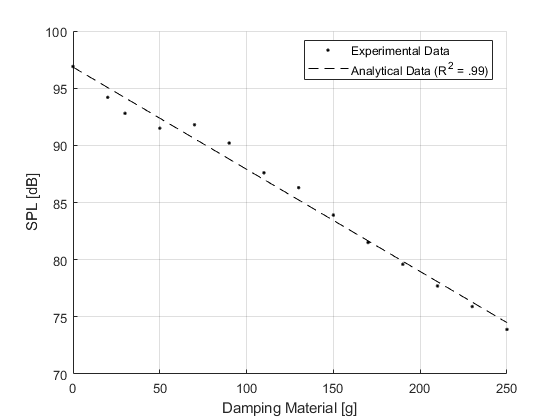

x = Scatter(:,9);
y_1 = Scatter(:,10);
format long
b_1 = x\y_1;
X = [ones(length(x),1) x];
b_01 = X\y_1;
scatter(x,y_1,'k.')
hold on
ylabel('SPL [dB]')
xlabel('Damping Material [g]')
xlim([0 250]);
%title('Linear Regression Relation Between Accidents & Population')
grid on
yCalc1 = X*b_01;
plot(x,yCalc1,'k--')
hold off
legend('Experimental Data','Analytical Data (R^2 = .99)','Location','best');

Rsq1 = 1 - sum((y_1 - yCalc1).^2)/sum((y_1 - mean(y_1)).^2);

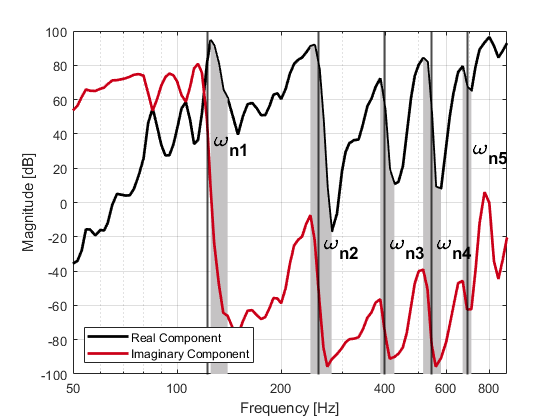

% Figure 13
f13 = figure('Name','Figure 13: Total Frequency Response', ...
    'NumberTitle','off');
x_1 = [122.5, 255.8, 397.3, 542.7, 690.1];
y_0 = [25, -35, -35, -35, 20];
labels = {'\bf \omega_{n1}','\bf \omega_{n2}','\bf \omega_{n3}','\bf \omega_{n4}','\bf \omega_{n5}'};
semilogx(DfV(:,5), DfV(:,6),'k', 'LineWidth', 2, 'DisplayName', 'Real Component')
hold on
xline(122.5,'k', 'LineWidth', 1.5, 'HandleVisibility','off')
xline(255.8,'k', 'LineWidth', 1.5, 'HandleVisibility','off')
xline(397.3,'k', 'LineWidth', 1.5, 'HandleVisibility','off')
xline(542.7,'k', 'LineWidth', 1.5, 'HandleVisibility','off')
xline(690.1,'k', 'LineWidth', 1.5, 'HandleVisibility','off')
area(Ar1(:,1), Ar1(:,2),'basevalue', -100,'FaceColor','#c5c3c4', 'HandleVisibility','off')
area(Ar2(:,1), Ar2(:,2),'basevalue', -100,'FaceColor','#c5c3c4', 'HandleVisibility','off')
area(Ar3(:,1), Ar3(:,2),'basevalue', -100,'FaceColor','#c5c3c4', 'HandleVisibility','off')
area(Ar4(:,1), Ar4(:,2),'basevalue', -100,'FaceColor','#c5c3c4', 'HandleVisibility','off')
area(Ar5(:,1), Ar5(:,2),'basevalue', -100,'FaceColor','#c5c3c4', 'HandleVisibility','off')
semilogx(DfV(:,5), DfV(:,7),'Color','#cb0018', 'LineWidth', 2, 'DisplayName', 'Imaginary Component')
hold off
text(x_1,y_0,labels,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',16)
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([-100 100]);
xlim([50 900]);
%Adds title
xticks([50 100 200 400 600 800])
xticklabels({'50', '100', '200', '400', '600', '800'})
%title('Total Frequency Response Graph');
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
legend('show', 'Location','SW')

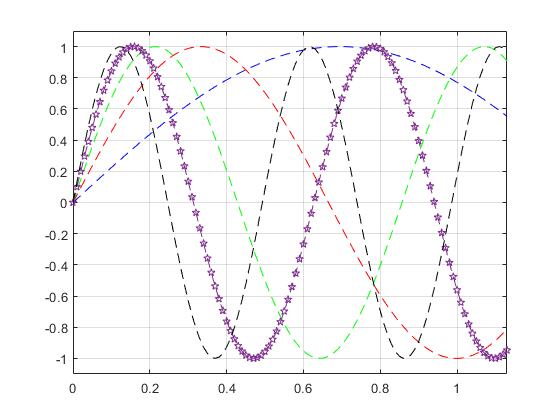

L = 1.13;
x = 0:0.01:1.2;
Lambda = [2.556, 5.3373, 8.2888, 11.3233, 14.3984];

A_t = sin((Lambda(1, 1).*x)./L);
B_t = sin((Lambda(1, 2).*x)./L);
C_t = sin((Lambda(1, 3).*x)./L);
D_t = sin((Lambda(1, 4).*x)./L);
E_t = sin((Lambda(1, 5).*x)./L);

plot(x,A_t,'b--')
hold on
plot(x,B_t,'r--')
plot(x,C_t,'g--')
plot(x,D_t,'p--')
plot(x,E_t,'k--')

%Adds grid to graph
grid on
%Adds box to outside of graph
box on
ylim([-1.1 1.1]);
xlim([0 1.13]);